Cleaning workspace

clear;
clc;

Loading data:

if isfile('data.mat')
     load('data.mat');
end

# Problem:

a = -1; % Left boundary
b = 1;  % Right boundary

u_a = 0; % Value at left boundary
u_b = 0; % Value at right boundary

n = 3; % How many coordinate functions to take
disp([ 'Solving problem with n=' num2str(n) ' coordinate functions']);

Solving problem with n=3 coordinate functions


# Matlab solution:

h = 0.05; % Step
X = linspace(a, b, (b-a)/h);
init_sol = bvpinit(X, [0 0]);
sol = bvp4c(@odefun, @bcfun, init_sol);
y_matlab = deval(sol, X);

# Galerkin method:

y_galerkin = Galerkin(a, b, n);

Solving system:
   -2.2622    0.5385    0.4520    2.6667
   -1.3457   -3.0292    0.6348   -0.5333
   -0.0279   -1.7789   -4.2084         0

Condition number of system:
    2.2292

Decomposition coefficients:
   -1.0843
    0.6056
   -0.2488



# Collocations method:

y_collocations = Collocations(a, b, n);

Solving system:
    0.3026    1.5515   -5.6315    2.8660
   -1.6667    2.0000    3.7500    2.0000
   -3.8047   -9.1201  -15.1854    1.1340

Condition number of system:
    8.2748

Decomposition coefficients:
   -0.9549
    0.8273
   -0.3323



# Plots:

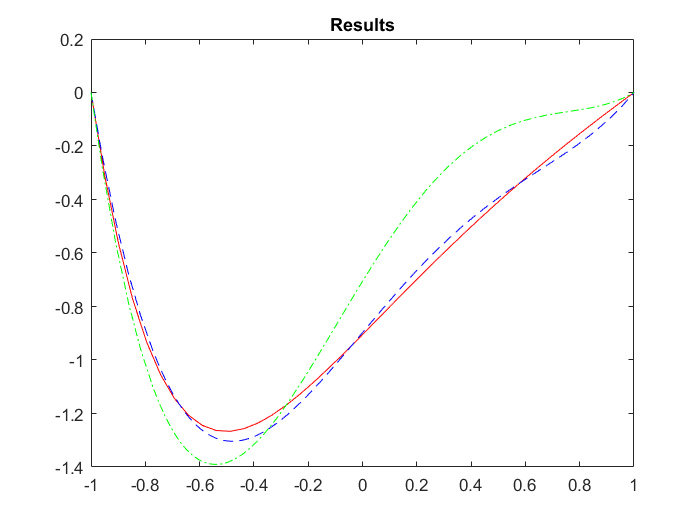

figure;
plot(X, y_matlab(1,:), '-r');
hold on;
fplot(y_galerkin, [a b], '--b');
fplot(y_collocations, [a b], '-.g');
title('Results');
hold off;

## Checking values at points:

points = [-0.5 0 0.5];
y_matlab_check = deval(sol, points);
for i = 1:length(points)
    point = points(i);
    disp([ 'Difference at x=' num2str(point) ':' ]);
    
    y_matlab_value = y_matlab_check(1, i);
    syms x;
    y_galerkin_value = vpa(subs(y_galerkin, x, point));
    y_galerkin_diff = y_matlab_value - y_galerkin_value;
    disp('  Galerkin: ');
    disp(y_galerkin_diff);
    
    y_collocations_value = vpa(subs(y_collocations, x, point));
    y_collocations_diff = y_matlab_value - y_collocations_value;
    disp('  Collocations: ');
    disp(y_collocations_diff);
end

Difference at x=-0.5:


  Galerkin: 


$$0.035283751264132158335928846071283$$

  Collocations: 


$$0.11619878294539401613477691554976$$

Difference at x=0:


  Galerkin: 


$$-0.0071223505128940184372154931224941$$

  Collocations: 


$$-0.19920750329688198532185339217904$$

Difference at x=0.5:


  Galerkin: 


$$-0.014918092847858309586694947057595$$

  Collocations: 


$$-0.26653469897537726291530946198804$$

#### Saving data:

save('data.mat');

#### Functions:

function dydx = odefun(x_, y)
    %p = @(x_actual)(subs(P(), x, x_actual));
    syms x;
    p = P();
    q = Q();
    r = R();
    f = F();
    dy_2 = subs((q/p) * y(2) + (r/p) * y(1) - (f/p), x, x_);
    dydx = [
        y(2);
        dy_2
    ];
end

function res = bcfun(ya, yb)
    res = [
        ya(1);
        yb(1)
    ];
end